## Questão 1 - Inversor de Onda Quadrada Monofásico

Load the simulated data:

load("data/Q1.mat");
q1_sim_data = ans;

a) Tensão de entrada e tensão na carga

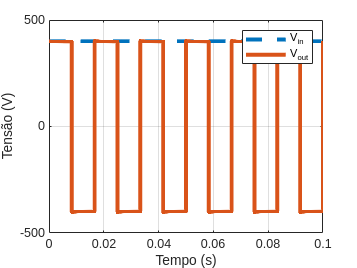

time = q1_sim_data.Time;
v_in = q1_sim_data.Data(:, 3);
v_out= q1_sim_data.Data(:, 4); 

plot(time, v_in, 'LineWidth',3, 'LineStyle','--'), hold on;
plot(time, v_out,'LineWidth',3), hold off;

legend("V_{in}", "V_{out}");
ylabel("Tensão (V)");
xlabel("Tempo (s)");
grid on;

b) Corrente de Entrada e Corrente na carga

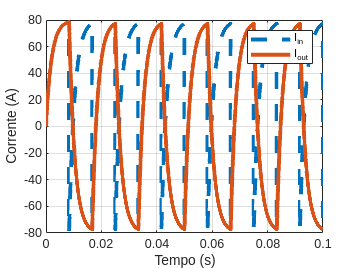

time = q1_sim_data.Time;
I_in = q1_sim_data.Data(:, 1);
I_out= q1_sim_data.Data(:, 2);


plot(time, I_in, 'LineWidth',3, 'LineStyle','--'), hold on;
plot(time, I_out,'LineWidth',3), hold off;

legend("I_{in}", "I_{out}");
ylabel("Corrente (A)");
xlabel("Tempo (s)");
grid on;

C) Potência Ativa Fornecida pela fonte

I_rms = rms(I_out)

I_rms = 58.8586

I_rms^2 * 5

ans = 1.7322e+04

d) FFT e THD da Corrente na Carga

Ts = diff(q1_sim_data.Time);
Ts = Ts(1)

Ts = 8.3333e-06


fs = 1/Ts;
f  = 0:(fs/length(q1_sim_data.Time)):(fs-1/fs);% Calculate the frequencies for the fft plot 
N = length(I_out);                             % Number of samples


xk = abs(fft(I_out)) / N;                      % Compute the double sided FFT
xk = xk(1:N/2);                                % Get the one-sided FFT

xk(2:end-1) = 2*xk(2:end-1);                   % Scale to get the magnetude in each 

plot(f(1:N/2), xk, 'LineWidth',3);

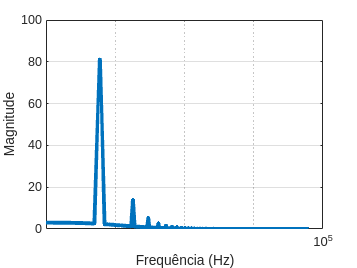

set(gca, 'XScale', 'log');
grid on;

ylabel("Magnitude");
xlabel("Frequência (Hz)");

thd_db = thd(I_out, fs, 5);
thd_percentage = 10^(thd_db/20)*100

thd_percentage = 18.4470

## Questão 2.1- Inversor de Bipolar

Load the simulated data:

load("data/Q2_bipolar.mat");
q2_sim_data = ans;

a) Tensão de entrada e tensão na carga

time = q2_sim_data.Time;
v_in = q2_sim_data.Data(:, 3);
v_out= q2_sim_data.Data(:, 4); 

plot(time, v_in, 'LineWidth',3, 'LineStyle','--'), hold on;

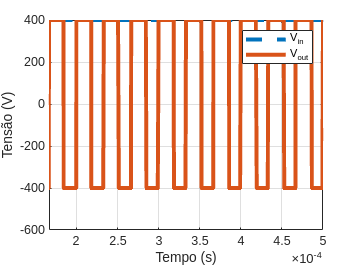

plot(time, v_out,'LineWidth',3), hold off;

legend("V_{in}", "V_{out}");
ylabel("Tensão (V)");
xlabel("Tempo (s)");
xlim([(1/30e3)*5 (1/30e3)*15]);
grid on;

b) Corrente de Entrada e Corrente na carga

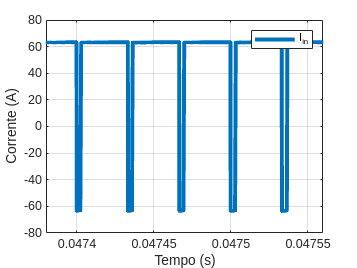

time = q2_sim_data.Time;

I_in = q2_sim_data.Data(:, 1);
plot(time, I_in, 'LineWidth',3, 'LineStyle','-');
legend("I_{in}")
ylabel("Corrente (A)");
xlabel("Tempo (s)");
xlim([47.38e-3 47.56e-3]);
grid on;

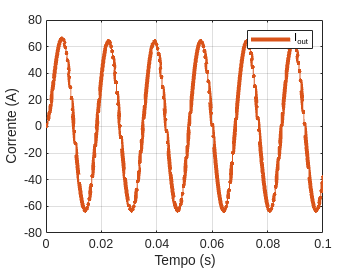

I_out= q2_sim_data.Data(:, 2);
plot(time, I_out,'LineWidth',3, 'Color',[0.8500 0.3250 0.0980]), hold off;

legend("I_{out}");
ylabel("Corrente (A)");
xlabel("Tempo (s)");
grid on;

C) Potência Ativa Fornecida pela fonte

I_rms = rms(I_out)

I_rms = 45.1916

I_rms^2 * 5

ans = 1.0211e+04

d) FFT e THD da Corrente na Carga

Ts = diff(q2_sim_data.Time);
Ts = Ts(1)

Ts = 1.6667e-07


fs = 1/Ts;
f  = 0:(fs/length(q2_sim_data.Time)):(fs-1/fs);% Calculate the frequencies for the fft plot 
N = length(I_out);                             % Number of samples


xk = abs(fft(I_out)) / N;                      % Compute the double sided FFT
xk = xk(1:N/2);                                % Get the one-sided FFT

xk(2:end-1) = 2*xk(2:end-1);                   % Scale to get the magnetude in each 

plot(f(1:N/2), xk, 'LineWidth',3);

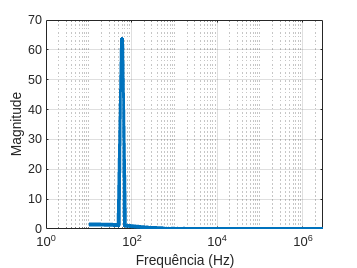

set(gca, 'XScale', 'log');
grid on;

ylabel("Magnitude");
xlabel("Frequência (Hz)");

thd_db = thd(I_out, fs, 5);
thd_percentage = 10^(thd_db/20)*100

thd_percentage = 3.6897